# ImpliedVolatility

**Overview**

The `ImpliedVolatility` chart creates a smooth, interpolated implied volatility surface for the observed option data $(T, K, \sigma, S)$, where

- $T$ is the expiry time of the option, measured in years;

- $K$ is the strike price of the option, in currency units (e.g., USD or GBP);

- $\sigma$ is the implied volatility, recorded as a decimal value in [0, 1];

- $S$ is the underlying asset price, in currency units.

The chart data comprises a table (`OptionData`) containing four numeric vector variables, namely $T$, $K$, $\sigma$and $S$ in that order. The observed option data is overlaid on the implied volatility surface for reference. The interpolation method for each volatility curve, or *smile*, is one of `linear`, `spline`, `pchip` (the default), `Hagan2002` and `Obloj2008`. The first three methods are non-parametric, and implemented using the `interp1` function. The latter two are variants of the SABR model for computing the implied Black volatility, and are implemented using the `blackvolbysabr` function. In this case the SABR model is calibrated using nonlinear least squares (`lsqnonlin`).

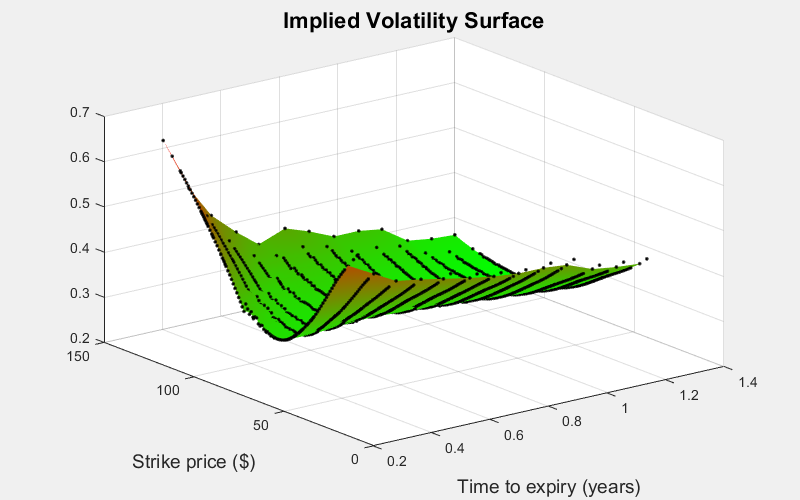

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'ImpliedVolatility.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'ImpliedVolatility'))) the source code for the `ImpliedVolatility` chart.

Documentation for [interp1](matlab: web(fullfile(matlabroot, 'help', 'matlab', 'ref', 'interp1.html'), '-helpbrowser')), [blackvolbysabr](matlab: web(fullfile(matlabroot, 'help', 'fininst', 'blackvolbysabr.html'), '-helpbrowser')), [lsqnonlin](matlab: web(fullfile(matlabroot, 'help', 'optim', 'ug', 'lsqnonlin.html'), '-helpbrowser')).

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.ImpliedVolatility

## Load the observed market data.

The market data comprises option expiry times, strike prices and implied volatilities. The times to expiry are divided into different bins, indicated by the variable `Group`. Volatility smiles corresponding to the times in each bin have similar shapes.

load( fullfile( galleryRoot(), '+Data', 'OptionData.mat' ) )

## Create a figure for the chart.

f = galleryFigure( 'Name', 'Implied Volatility Example', ...
    'Toolbar', 'figure' );

## Create the chart.

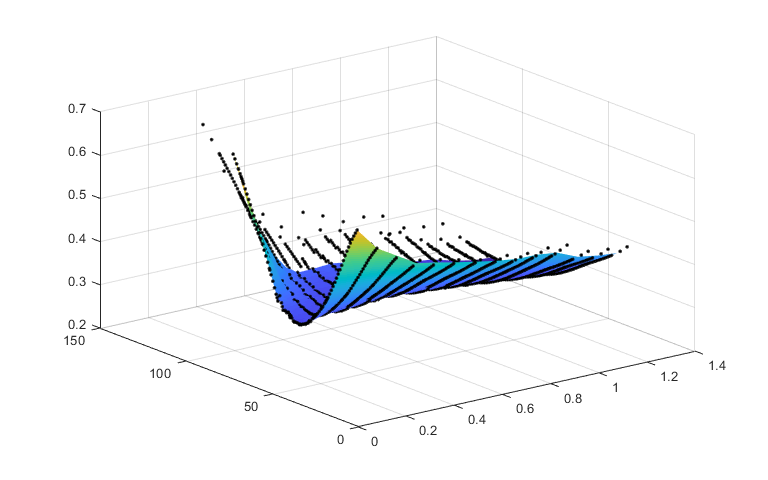

D1 = D(D.Group == 'G1', 1:4);
IV = ImpliedVolatility( 'Parent', f, 'OptionData', D1 );

## Annotate the chart.

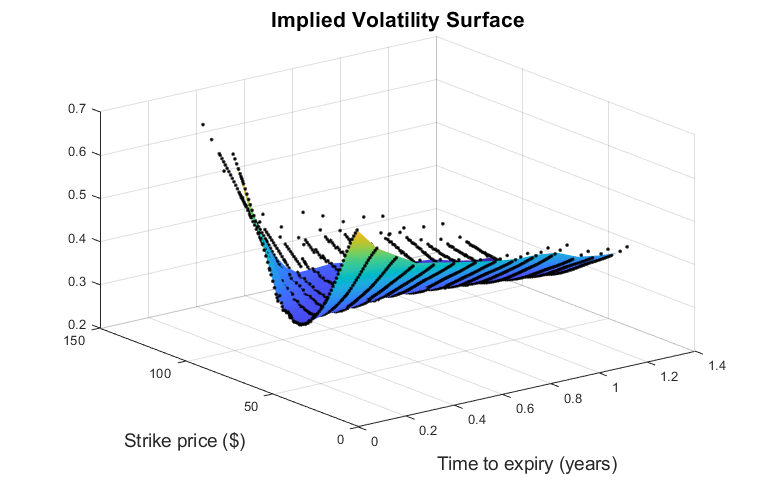

set( IV.XLabel, 'String', 'Time to expiry (years)', 'FontSize', 14 )
set( IV.YLabel, 'String', 'Strike price ($)', 'FontSize', 14 )
set( IV.Title, 'String', 'Implied Volatility Surface', 'FontSize', 16 )

## Create a custom colormap and apply it to the chart.

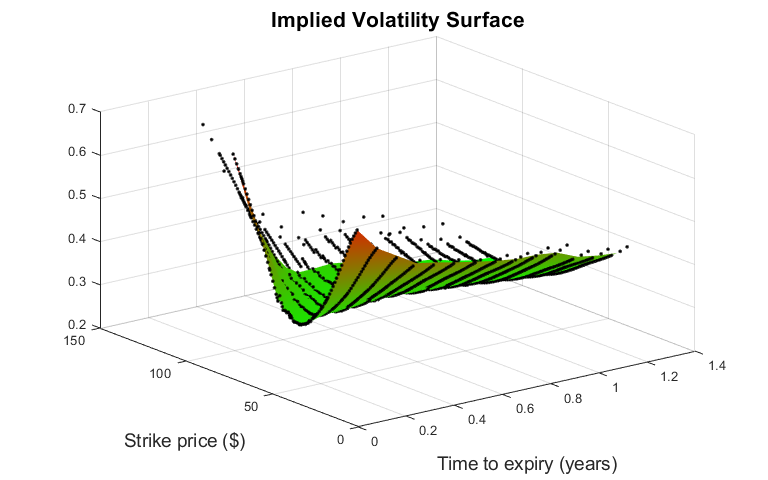

t = linspace( 0, 1, 256 ).';
money = [t, flip(t), zeros( size( t ) )];
IV.Colormap = money;

## Restrict the strike prices to lie between $60 and $100.

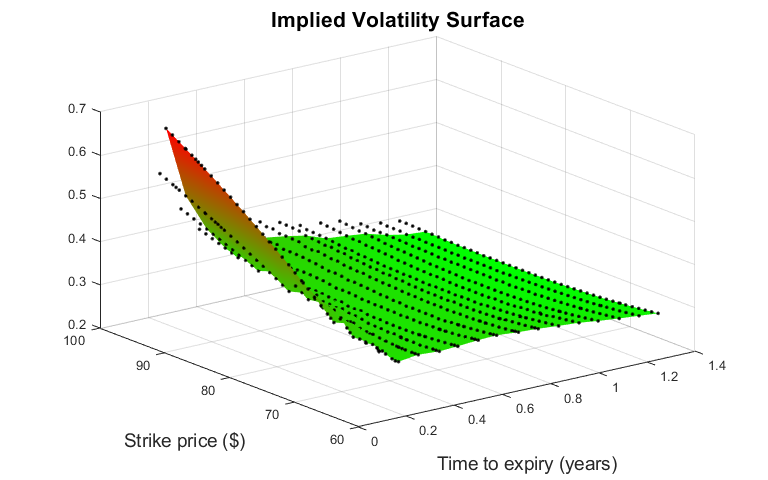

newData = D1(D1.StrikePrice >= 60 & D1.StrikePrice <= 100, :);
IV.OptionData = newData;

## Remove the first expiry time from the surface.

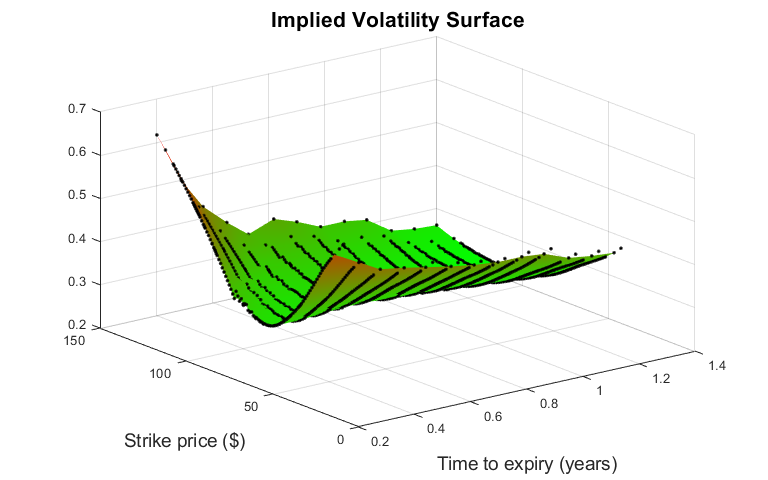

newData = D1(D1.ExpiryTime > D1.ExpiryTime(1), :);
IV.OptionData = newData;

## Create multiple charts on separate figures.

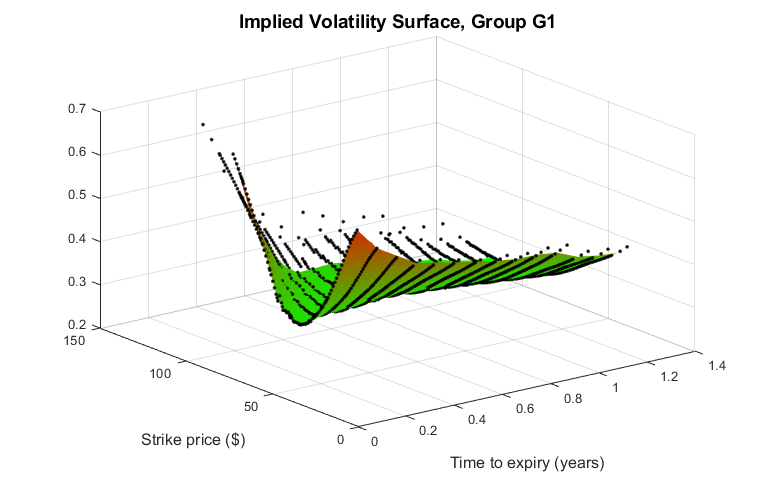

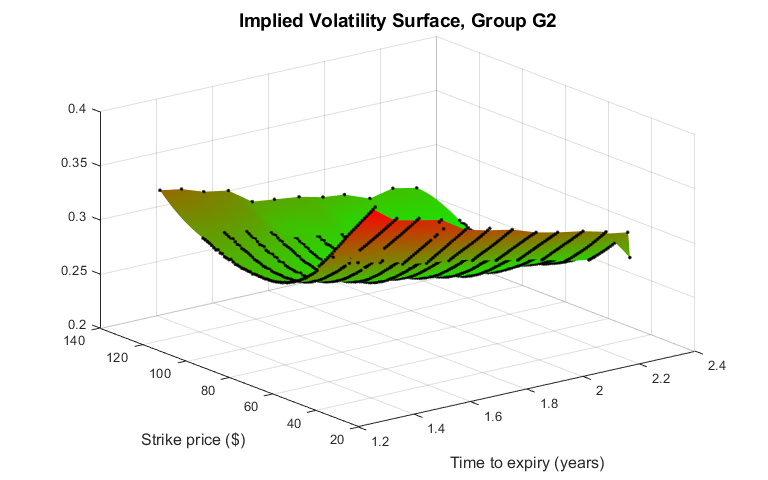

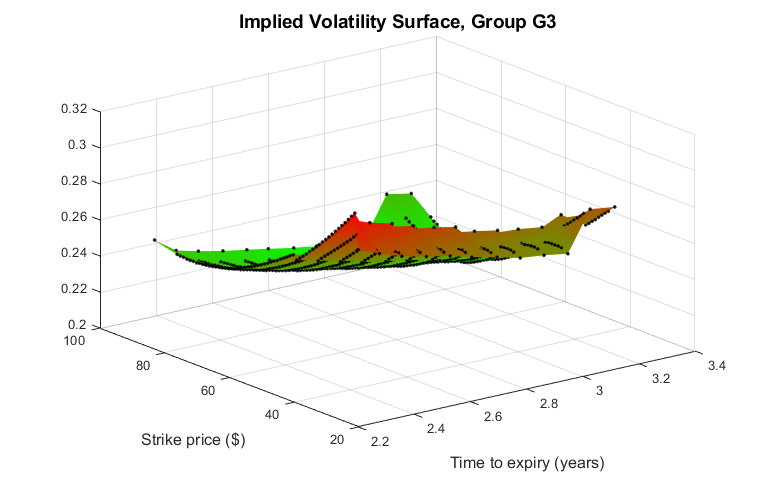

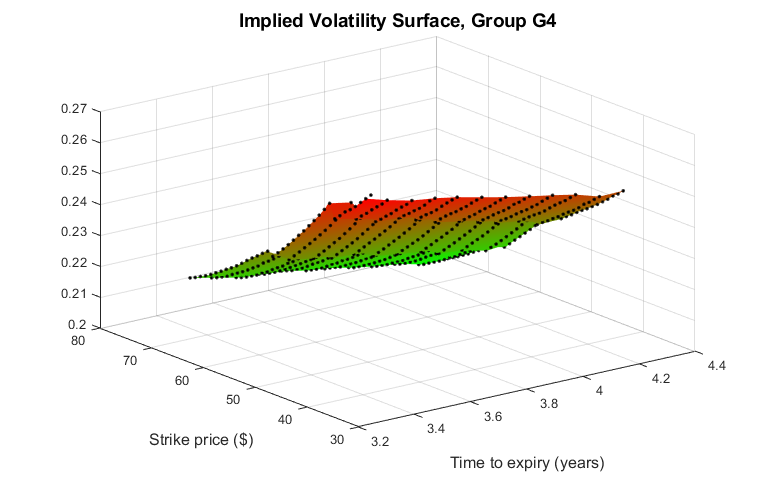

ivCharts = cell( 4, 1 );
groupFigures = gobjects( 4, 1 );
for k = 1 : 4
    s = ['G', int2str( k )];
    currentD = D(D.Group == s, 1:4);
    groupFigures(k) = galleryFigure( ...
        'Name', ['Implied Volatility, Group ', s], ...
        'Toolbar', 'figure' );
    ivCharts{k} = ImpliedVolatility( 'Parent', groupFigures(k), ...
        'OptionData', currentD, 'Colormap', money );
    set( ivCharts{k}.XLabel, 'String', 'Time to expiry (years)', 'FontSize', 12 )
    set( ivCharts{k}.YLabel, 'String', 'Strike price ($)', 'FontSize', 12 )
    set( ivCharts{k}.Title, ...
        'String', ['Implied Volatility Surface, Group ', s], 'FontSize', 14 )
end

## Change the surface interpolation method for a specific chart.

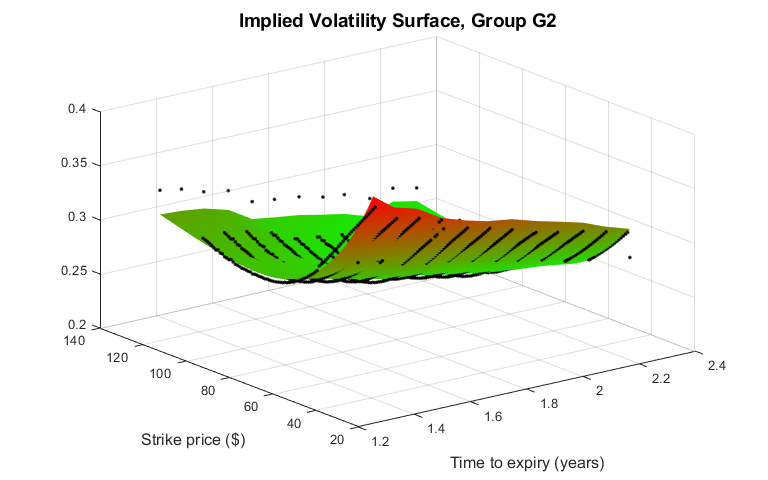

ivCharts{2}.InterpolationMethod = 'Hagan2002';